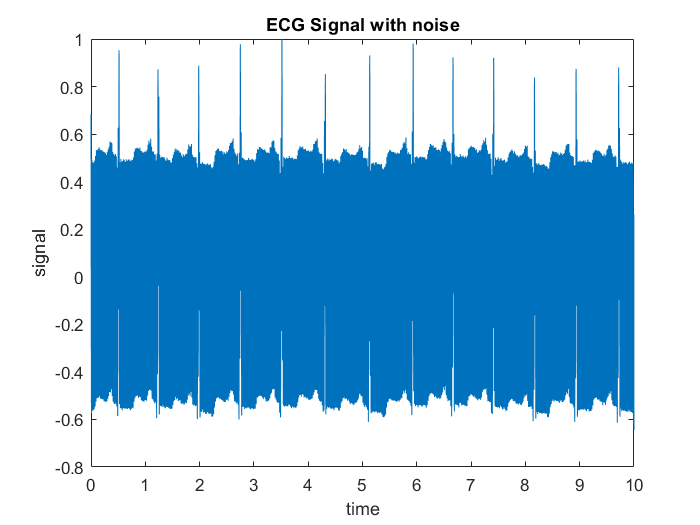

clear
%Loading Data
data =load('ecg_data.txt');
t=data(:,1);
x=data(:,2);
fs=1000;
% Plotting the ECG signal
plot(t,x);
title("ECG Signal with noise");
xlabel("time");
ylabel('signal');

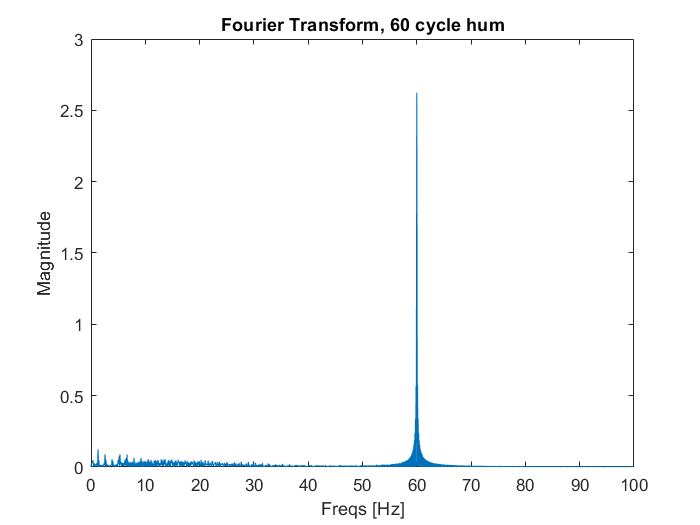

%Locating the noise of the signal
myFFT(x, fs);
title('Fourier Transform, 60 cycle hum')
ylabel('Magnitude');
xlabel('Freqs [Hz]');
xlim([0,100]); %Noise at 60 Hz

%Creating a butter filter
fc=60;
wc=2*pi*20; %normalized cutoff frequency
[num, dem] = butter(3,wc,"low","s");
h=tf(num,dem)          % Convert to SOS form


h =
 
                 1.984e06
  ---------------------------------------
  s^3 + 251.3 s^2 + 3.158e04 s + 1.984e06
 
Continuous-time transfer function.



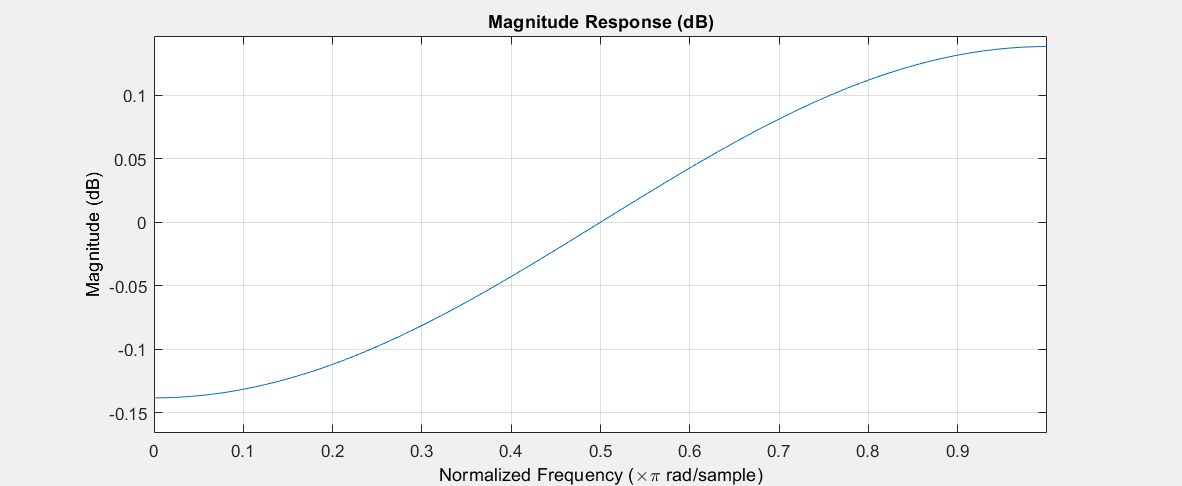

h1 =   Figure (filtervisualizationtool) with properties:

      Number: 4
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 945.6000 388.8000]
       Units: 'pixels'

  Use get to show all properties


h1=fvtool(num,dem)

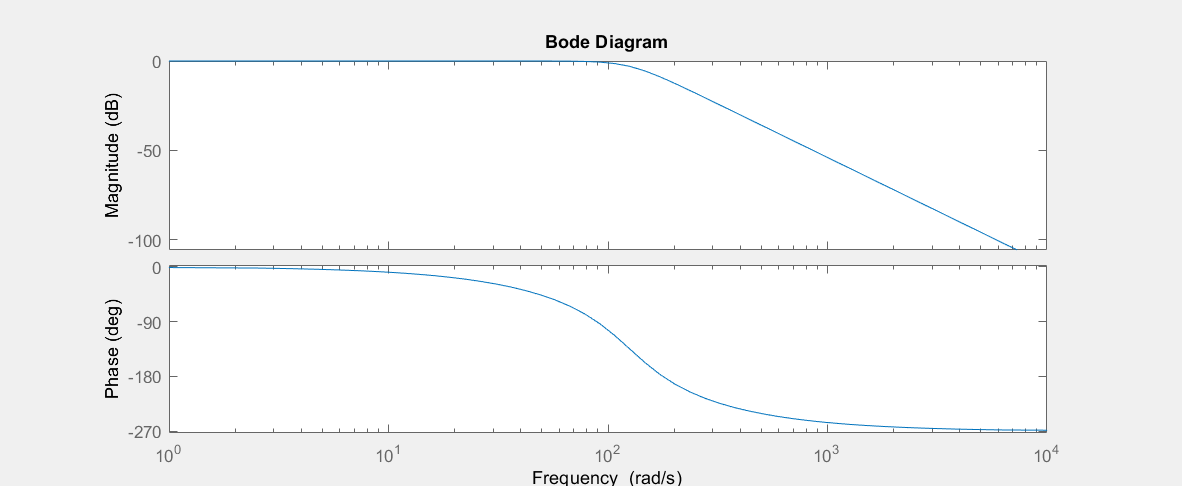

bode(h)

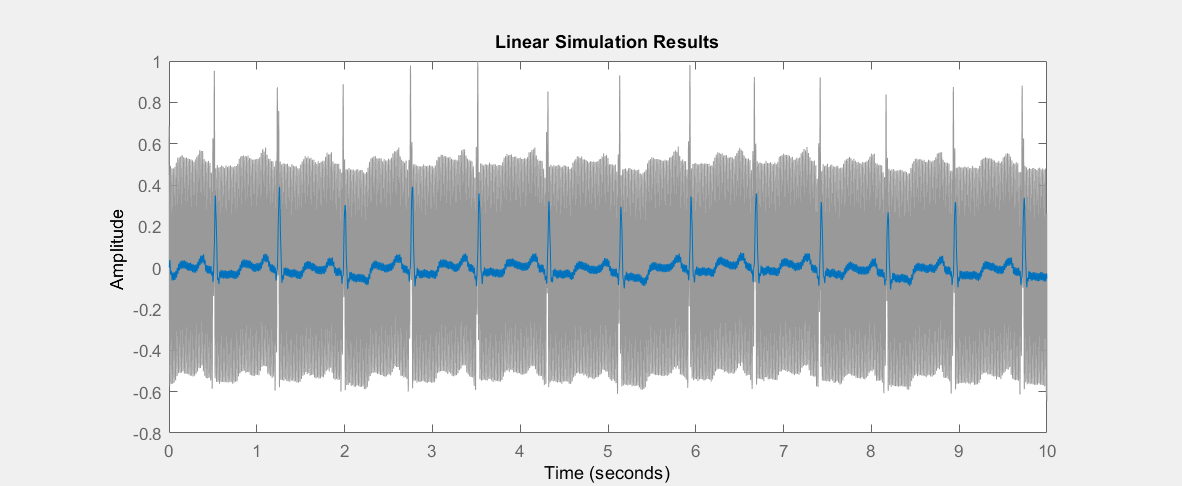

%simulating to find y(t)
lsim(h,x,t)

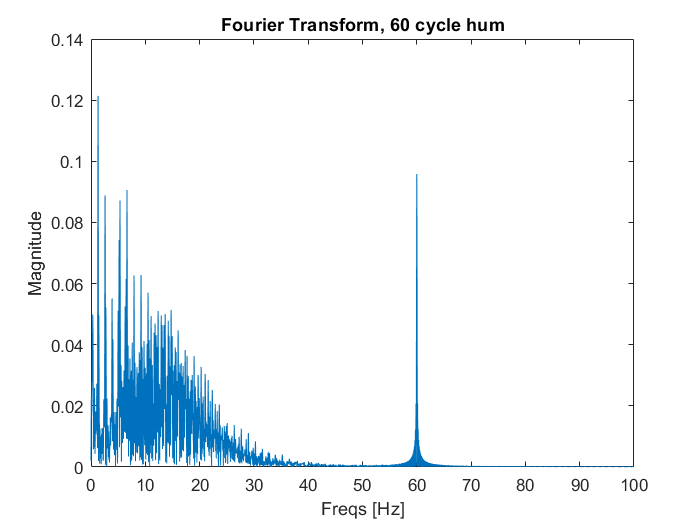

y=lsim(h,x,t); %In time domain
myFFT(y,fs) %In Frequency domain
title('Fourier Transform, 60 cycle hum')
ylabel('Magnitude');
xlabel('Freqs [Hz]');
xlim([0,100]); %Noise at 60 Hz